# Homework 18

#### 12110807 ChuyeZhang

Define a vector to express coefficient

t_f=3;
theta1_i=pi/6;
theta1_f=pi/2;
theta2_i=pi/5;
theta2_f=pi/2;


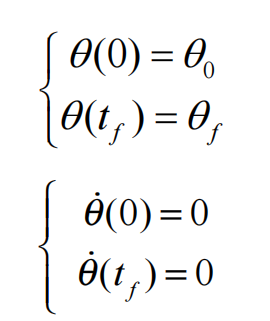

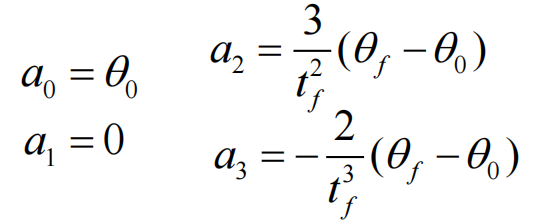

a1=[0 0 0 0];
a1(1)=theta1_i;
a1(2)=0;
a1(3)=3/t_f^2*(theta1_f-theta1_i);
a1(4)=-2/t_f^3*(theta1_f-theta1_i);

a2=[0 0 0 0];
a2(1)=theta2_i;
a2(2)=0;
a2(3)=3/t_f^2*(theta2_f-theta2_i);
a2(4)=-2/t_f^3*(theta2_f-theta2_i);

t=0:0.01:3

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


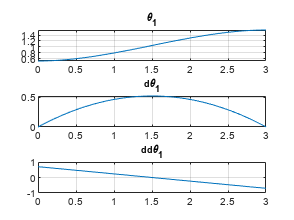


theta1=a1(1)+a1(2)*t+a1(3)*t.^2+a1(4)*t.^3;
dtheta1=a1(2)+a1(3)*t*2+3*a1(4)*t.^2;
ddtheta1=a1(3)*2+6*a1(4)*t;

theta2=a2(1)+a2(2)*t+a2(3)*t.^2+a2(4)*t.^3;
dtheta2=a2(2)+a2(3)*t*2+3*a2(4)*t.^2;
ddtheta2=a2(3)*2+6*a2(4)*t;

figure
subplot(3,1,1),plot(t,theta1),title('\theta_1'),grid
subplot(3,1,2),plot(t,dtheta1),title('d\theta_1'),grid
subplot(3,1,3),plot(t,ddtheta1),title('dd\theta_1'),grid

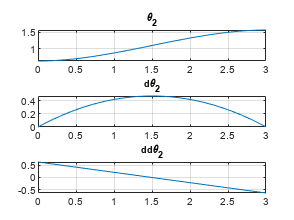


figure
subplot(3,1,1),plot(t,theta2),title('\theta_2'),grid
subplot(3,1,2),plot(t,dtheta2),title('d\theta_2'),grid
subplot(3,1,3),plot(t,ddtheta2),title('dd\theta_2'),grid

Simulation for the trajectory:

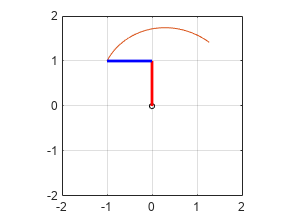

l=1;
x=[];
y=[];
figure
for i=1:length(t)
pause(.005)
xm1=l*cos(theta1(i));
ym1=l*sin(theta1(i));
xm2=xm1+l*cos(theta1(i)+theta2(i));
ym2=ym1+l*sin(theta1(i)+theta2(i));
x=[x,xm2];
y=[y,ym2];
plot([0],[0],'ko','MarkerSize',4),grid; %pivot point
hold on
plot(x,y)
plot([0 xm1],[0 ym1],'r','LineWidth',2);% first arm
plot([xm1 xm2],[ym1 ym2],'b','LineWidth',2);% second arm
axis([-2*l 2*l -2*l 2*l]);
axis square
hold off
end